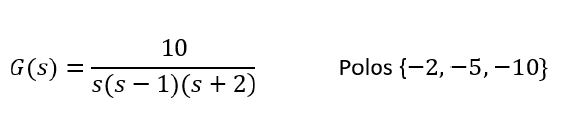

%Ejercicio 10 de el taller de practica
%Hallar vector de ganancia k y prefiltro
s=tf('s');
G=(10)/(s*(s-1)*(s+2))


Ge=ss(G) %Para hallar la matriz de espacio de estados
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(G)
Mc=rank(ctrb(A,B))

%Escribir manualmente el valor de los polos deseados
P=[-2 -5 -10];

k=acker(A,B,P) %Hallar compensador

Alc=A-B*k; %Retroalimentacion
Gc=ss(Alc,B,C,0) %Sistema compensado en ganancia
GC1=tf(Gc) %Pasamos de espacio de estados a TF

F=1/dcgain(Gc) %Precompensador

step(GC1*F) %Aplicamos precompensador
stepinfo(GC1)%Graficamos compensado vs identifiacada
pole(GC1)% para observar donde quedaron nuestros polos


%Ejercicio 8
%Hallar vector k y prefiltro

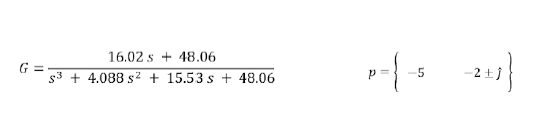

s=tf('s');
G=((16.02*s)+48.06)/(s^3+(4.088*s^2)+(15.53*s)+48.06)

Ge=ss(G) %Para hallar la matriz de espacio de estados
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(G)
Mc=rank(ctrb(A,B))

%Escribir manualmente el valor de los polos deseados
P=[-5 -2+i -2-i];

k=acker(A,B,P) %Hallar compensador

Alc=A-B*k; %Retroalimentacion
Gc=ss(Alc,B,C,0) %Sistema compensado en ganancia
GC1=tf(Gc) %Pasamos de espacio de estados a TF

F=1/dcgain(Gc) %Precompensador

step(GC1*F) %Aplicamos precompensador
stepinfo(GC1)%Graficamos compensado vs identifiacada
pole(GC1)% para observar donde quedaron nuestros polos
